# Challenges of Non-Stationary Biomedical Signals 

Non-stationary signals are signals whose statistical properties, such as mean and variance, change over time. We will start out by creating one. 

% set hte sampling rate of the signal as 1 KHz as varabile Fs
Fs = 1e3; 

% Duration of sginal as 1 second
t = 0:1/Fs:1-1/Fs; 

% Tone at 200 Hz after 0.7 seconds
comp1 = cos(2*pi*200*t).*(t>0.7); 

% Tone at 60 Hz between 0.1 and 0.3 seconds
comp2 = cos(2*pi*200*t).*(t>0.1 & t<0.3);

% Low frequency trend at 0.5 Hz
trend = sin(2*pi*1/2*t); 
rng default; 

% Noise
wgnNoise = 0.4*randn(size(t)); 

% Signal with all parts combined
x = comp1 + comp2 + trend + wgnNoise; 


We can visualize the signal using plot. 

% Visualize
plot(t,x); 
xlabel("second"); 
ylabel("Amplitude");

## Use Signal Analyzer to understand the signal better

Now we have data x in the workspace. Open **Signal Analyzer** and drag the timetable from the **Workspace Browser** to the Signal table. Click **Display Grid** to create two side-by-side displays. Select each display and, in the **Display** tab, click **Time-Frequency** to add a spectrogram view.

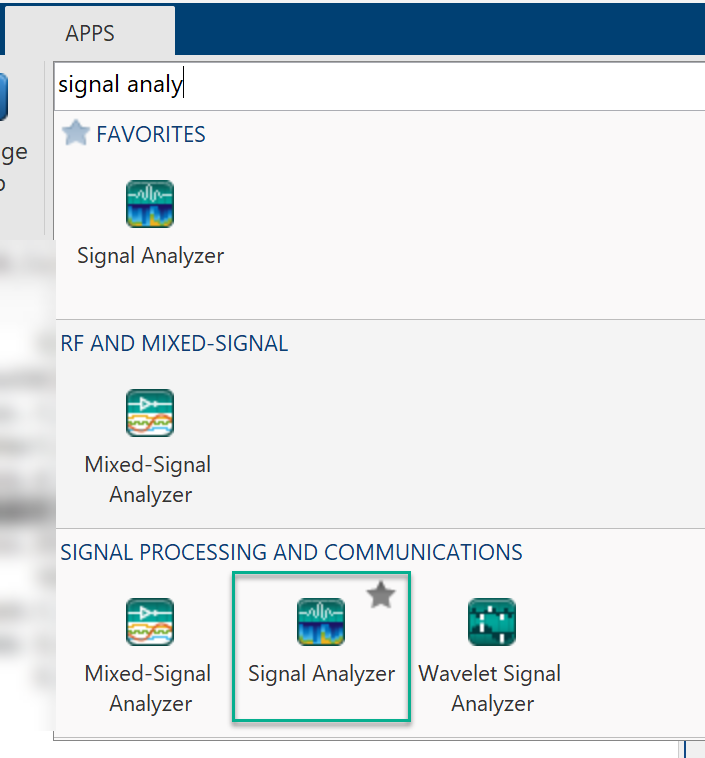

In the Signal Analyzer, you can drag and drop signals from your MATLAB workspace to view the signal. You can pan and focus on regions of interest. Look into the frequency spectrum of the signal. You can analyze the signal in the time-frequency domain with the spectrogram and scalogram. For now, we will turn on the persistent spectrum (The *persistence spectrum* is a time-frequency view that shows the percentage of the time that a given frequency is present in a signal. The persistence spectrum is a histogram in power-frequency space.) 

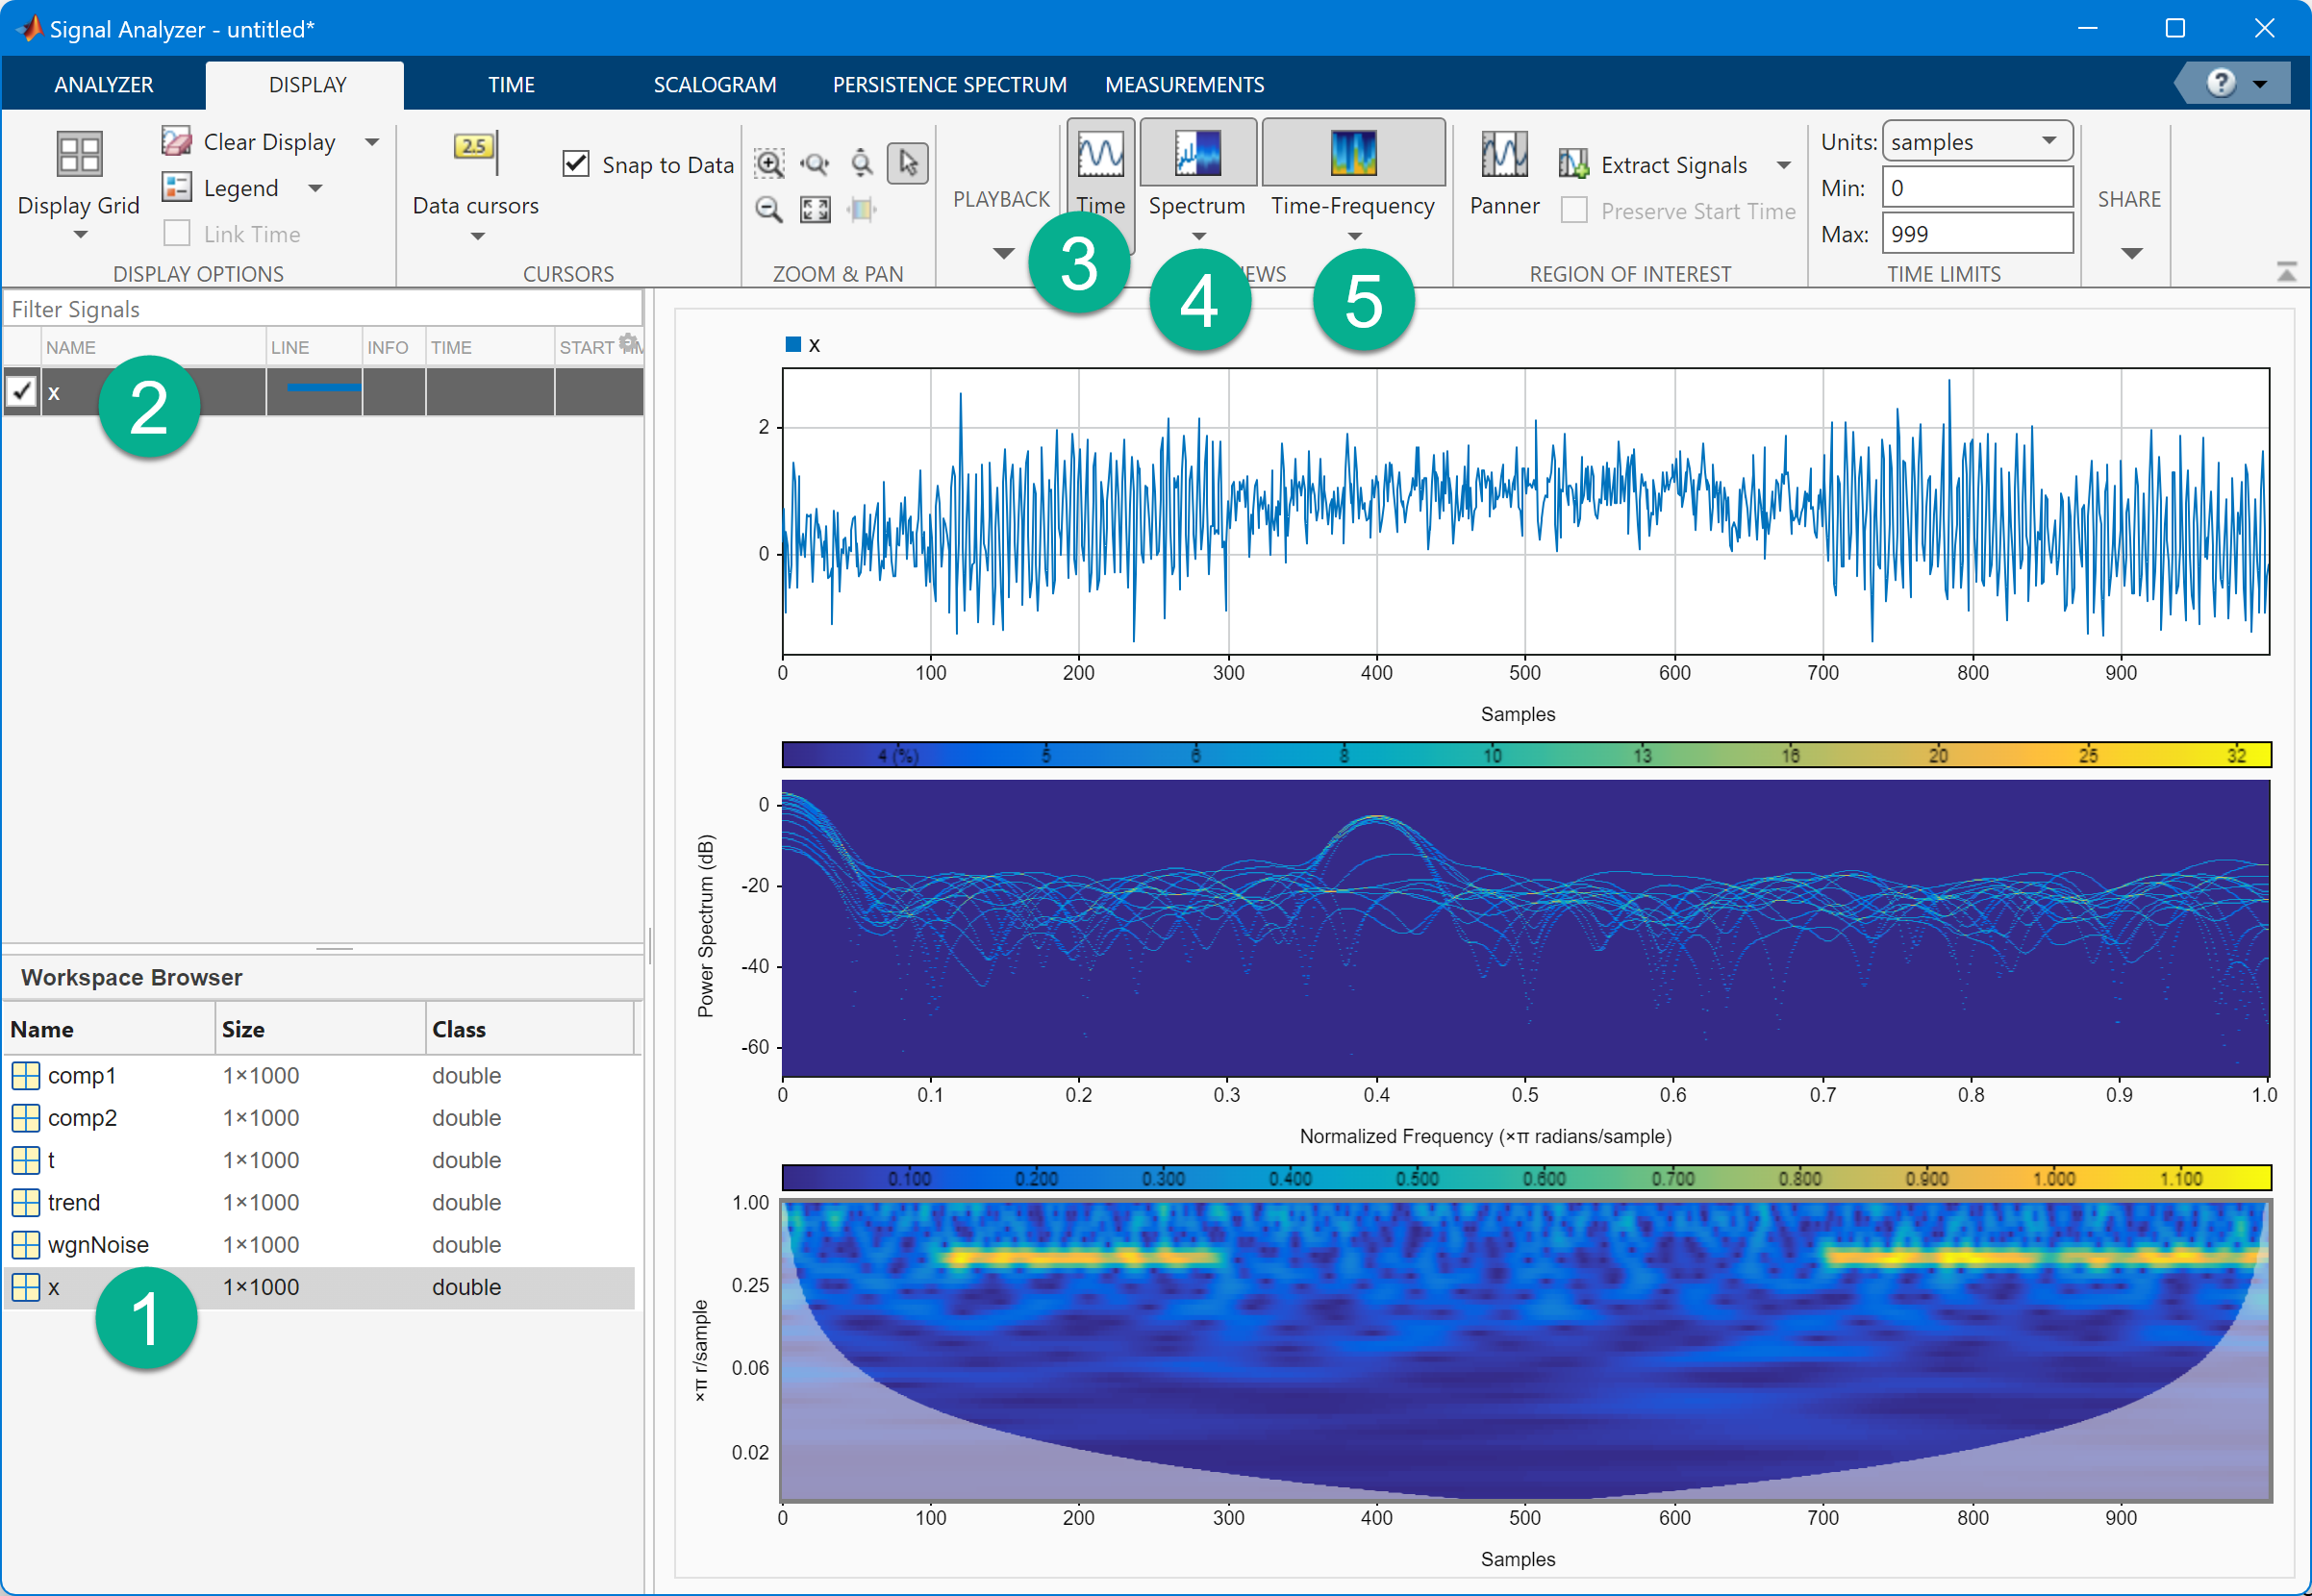

# Visualize and Recreate EWT Decomposition

We will now use Signal Multiresolution Analyzer to study this signal. The **Signal Multiresolution Analyzer** app is an interactive tool for visualizing multilevel wavelet- and data adaptive-based decompositions of real-valued 1-D signals and comparing results. 

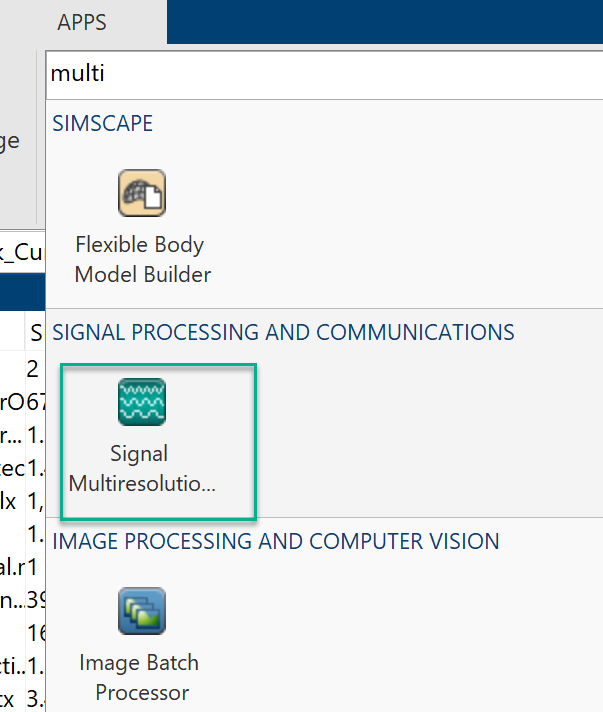

Or use commandline interface. 

signalMultiresolutionAnalyzer

On the **Analyzer** tab, click **Import **. A window appears with a list of all the workspace variables the app can process. Select the `wecg` signal and click **Import**. After a brief, one-time initialization, the name and type of the imported signal populates the **Signals** pane.